# Gráficas en Matlab

Para evaluar una función $f(x,y)$  en un dominio  $D = [a,b] x [c,d]$, crearemos un mallado con la ayuda de la función *meshgrid(x,y).*

**Ejemplo: **

Sea $f(x,y)=x^2 y$ en el dominio $–2<x<2, -3<y<3$ 

%[X, Y]=meshgrid(-10:0.1:1,-12:0.1:4); 
%Z = sin(X+Y)+(X-Y).^2-1.5*X+2.5*Y+1; % MCCORMICK FUNCTION
%[X, Y]=meshgrid(-10:0.1:10,-10:0.1:10); 
%Z = ((X.^2)/4000)+((Y.^2)/4000)-cos(X).*cos((Y)/(sqrt(2)))+1; % GRIEWANK FUNCTION
%[X, Y]=meshgrid(-4:0.1:4,-4:0.1:4); 
%Z =  (X-1).^2 + (Y-1).^2 - X.*Y; % TRID FUNCTION
%[X, Y]=meshgrid(-2:0.05:2,-1:0.05:1);
%Z = ((4-2.1*X.^2+((X.^4)/3)).*X.^2)+X.*X+(-4+4.*Y.^2).*Y.^2; % SIX-HUMP CAMEL FUNCTION
%[X, Y]=meshgrid(-5:0.1:5,-5:0.1:5); 
%Z = -cos(X).*cos(Y).*exp(-(X-pi).^2-(Y-pi).^2); %EASON
%[X, Y]=meshgrid(0:0.05:4,0:0.05:4);
%Z = -sin(X).*(sin((1/pi)*X.^2)).^(20)-sin(Y).*(sin(2/pi*Y.^2)).^20; %MICHATEWICZ
[X, Y]=meshgrid(-10:0.1:10,-10:0.1:10);
Z = -0.0001*(abs(sin(X).*sin(Y).*exp(abs(100-(sqrt(X.^2 + Y.^2)/pi))))+1).^0.1;
%Z =-0.0001.*(abs(sin(X).*sin(Y).*exp(abs(100-(sqrt(X.^2+Y.^2)./pi))))+1).^(0.1);


% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%Z = X.^3 - X.*Y + Y.^2 - 2*X + 3*Y -4;
%Z = ((Y-((5.1/(4*pi^2)).*X.^2)+((5.*X)/pi)-6).^2+((10.*(1-(1/(8*pi)))).*cos(X))+10);
%Z=X.^2.* Y;
%Z = 8.*X.^2 + 4.*X.*Y +5.*Y.^2;
%Z = 2.*X.^2+4.*X.*Y-10.*X.*Y+Y.^2;
%Z = (X-2).^2+(X-2*Y.^2).^2;
%Z = 25*X.^2-12.*X.^4-6.*X.*Y+25.*Y-24.*X.^2.*Y.^2-12.*Y.^2;

Ahora para plotear en 3D usamos *plot3(X,Y,Z) *

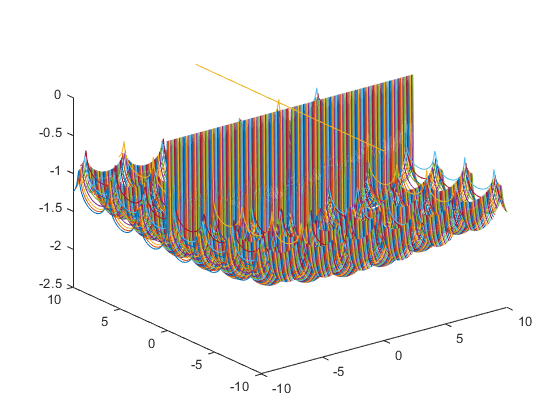

plot3(X,Y,Z)

Por otra parte, podemos ver el gráfico de superfice de la función 

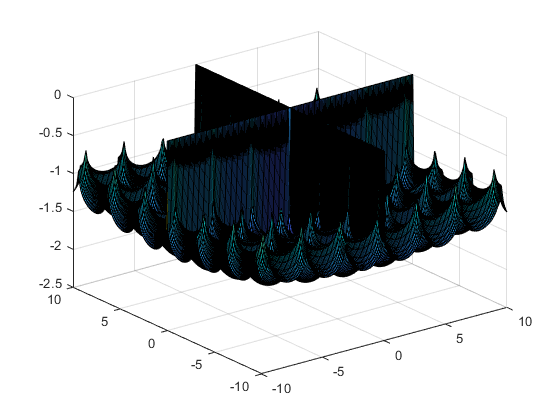

surf(X,Y,Z)

Y a este mismo, agregarle sus curvas de nivel

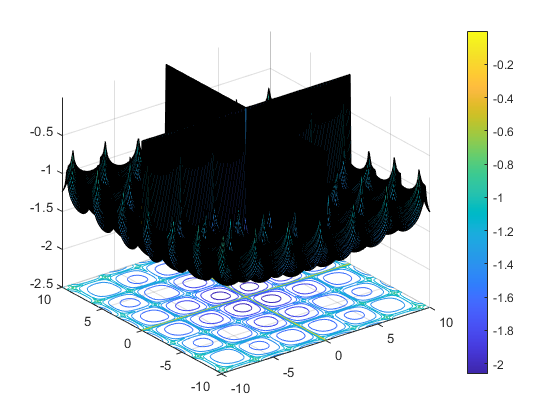

surfc(X,Y,Z)
colorbar

Otra representación disponible son los gráficso de malla. 

*mesh() * Representa el gráfico de malla

*meshc() *Incluye las curvas de nivel

*meshz() *Incluye una cortina en la parte inferior de la función.

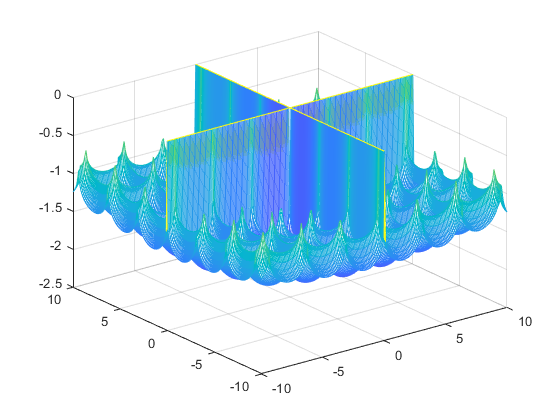

mesh(X,Y,Z)

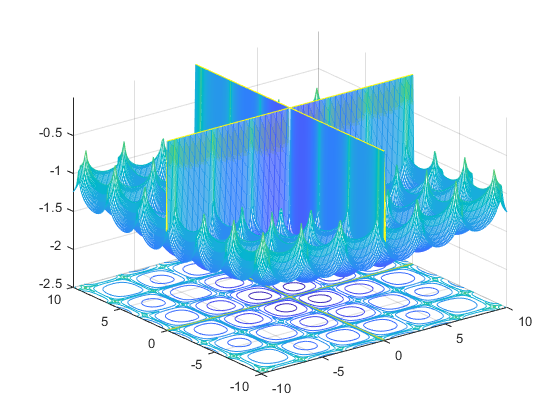

meshc(X,Y,Z)

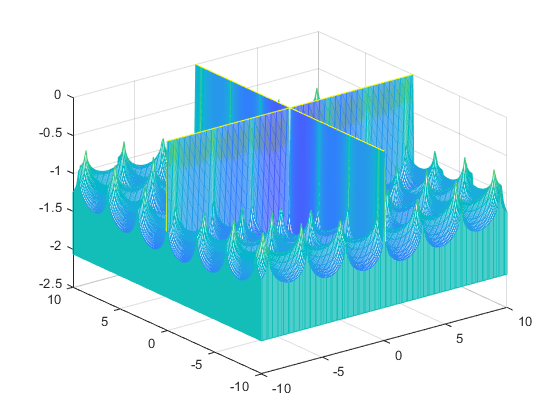

meshz(X,Y,Z) 

También tenemos gráficos de contorno en dos opciones.

*contour(Z,n) *Nos da las curvas de nivel de Z usando n líneas.

*contour3(Z,n) *Contorno en 3D

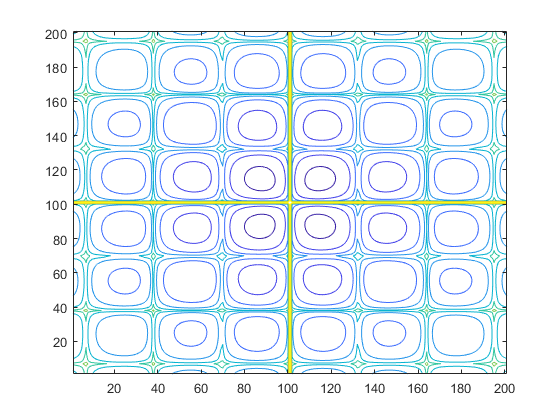

contour(Z)

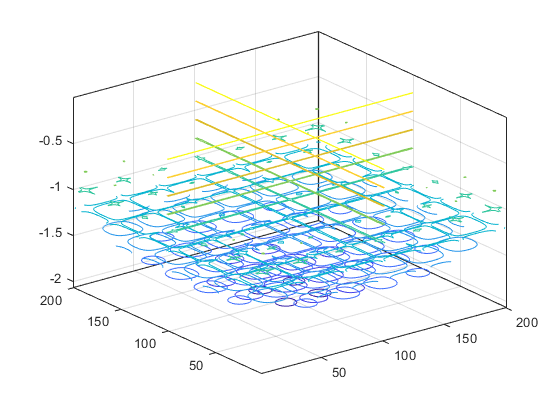

contour3(Z)

Por último, está el gráfico de densidad

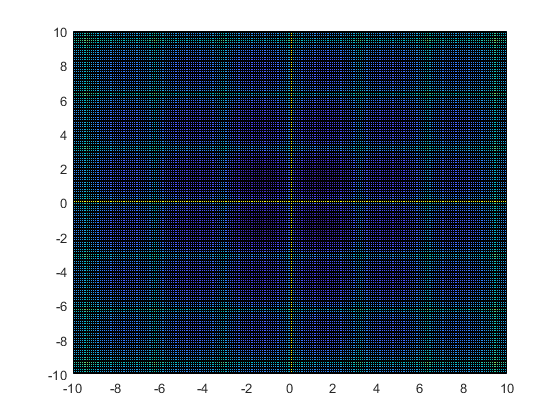

pcolor(X,Y,Z)

Ahora, para la representacion, *view([x,y,z]) *sitúa el punto de vista de la figura en el punto indicado y *ginput *nos devuelve las coordenadas $(x,y)$ del punto una vez seleccionado en la gráfica.